# Weather analysis

2024-01-03

## Prepare data

apiKey ="b1b15e88fa797225412429c1c50c122a1";

% Define the location for which you want the weather forecast
cityName = "Muenchen"; 
countryCode = "DE";

% Create the URL for the API call
url = sprintf("http://samples.openweathermap.org/data/2.5/forecast?q=%s,%s&appid=%s", cityName, countryCode, apiKey);
if true
    % Send the web request to the OpenWeatherMap API
    response = webread(url);
    
    % Assuming "response" is the struct obtained from the OpenWeatherMap API
    data = parseForecast(response.list);
    data = struct2table(data);
    if true
        data
    end 
end

data = 36x6 table
            date            temperature     weather      clouds    wind         details     
    ____________________    ___________    __________    ______    ____    _________________

    16-Feb-2017 12:00:00      286.67       {'Clear' }       0      1.81    {'clear sky'    }
    16-Feb-2017 15:00:00      285.66       {'Clear' }       0      1.59    {'clear sky'    }
    16-Feb-2017 18:00:00      277.05       {'Clear' }       0      1.41    {'clear sky'    }
    16-Feb-2017 21:00:00      272.78       {'Clear' }       0      2.24    {'clear sky'    }
    17-Feb-2017 00:00:00      273.34       {'Clouds'}      76      3.59    {'broken clouds'}
    17-Feb-2017 03:00:00      275.57       {'Rain'  }      76      3.77    {'light rain'   }
    17-Feb-2017 06:00:00      276

## Modeling

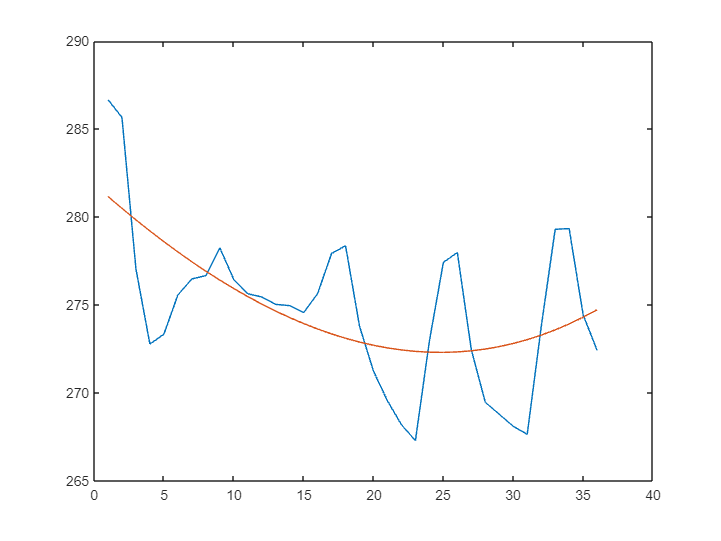

if true
    n = 3;
    X = (1:36);
    y = data.temperature;
    p = polyfit(X,y,n);
    y1 = polyval(p,X);
    plot(X,y,X,y1)
end

## Helper function

function forecastData = parseForecast(responseList)
    % Initialize an array of structs to hold the parsed forecast data
    forecastData = struct("date", {}, "temperature", {}, "weather", {}, "clouds", {}, "wind", {}, "details", {});

    % Loop through each entry in the responseList cell array
    for i = 1:length(responseList)
        % Get the current forecast struct
        forecastStruct = responseList{i};

        % Extract the date and time of the forecast
        forecastData(i).date = datetime(forecastStruct.dt, "ConvertFrom", "posixtime");

        % Extract main forecast data like temperature
        forecastData(i).temperature = forecastStruct.main.temp;

        % Extract weather conditions
        forecastData(i).weather = forecastStruct.weather(1).main;

        % Extract cloud data
        forecastData(i).clouds = forecastStruct.clouds.all;

        % Extract wind data
        forecastData(i).wind = forecastStruct.wind.speed;

        % Extract additional details if needed
        forecastData(i).details = forecastStruct.weather(1).description;
    end
end